# HW5 - ME652 허수민 20203691

close all; clear; clc;

## Problem 1

- Range from vehicle to landmarks ($\rho_{i\;}$)


$$\rho_{i\;} =\sqrt{\;{\left(x_i -x_0 \right)}^{2\;} +{\left(y_i -y_0 \right)}^{2\;} }$$


- Bearing angle from vehicle to landarks ($\beta_{i\;}$)


$$\beta_{i\;} ={\mathrm{tan}}^{-1} \left(\frac{y_i -y_0 }{x_i -x_0 }\right)-\psi \;$$


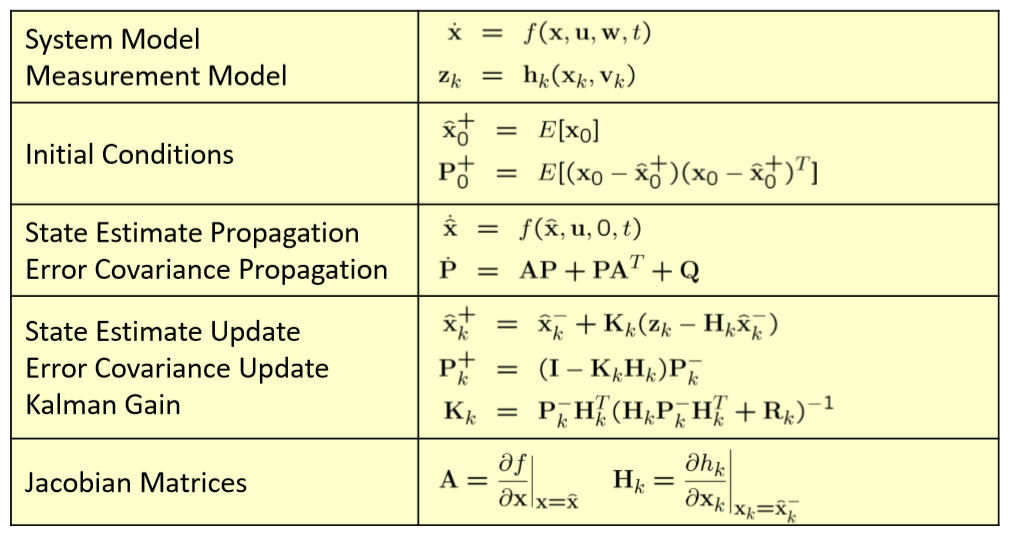

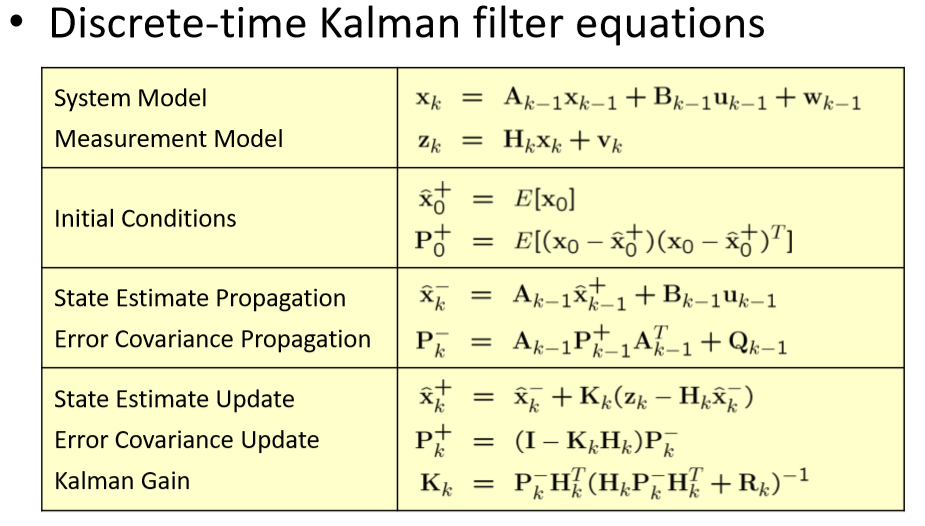

### **jacobian Matrix A**

- 
$$\mathrm{size}\left(A\right)=14\;\mathrm{by}\;14$$


- 
$$A\left(1,3\right)=\frac{\delta \left\lbrace V\;\mathrm{cos}\left(\psi \right)\right\rbrace }{\delta \left\lbrace \psi \right\rbrace \;}=-V\;\mathrm{sin}\left(\psi \right)$$


- 
$$A\left(2,3\right)=\frac{\delta \left\lbrace V\;\mathrm{sin}\left(\psi \right)\right\rbrace }{\delta \left\lbrace \psi \right\rbrace \;}=V\;\mathrm{cos}\left(\psi \right)$$


- 
$$A\left(1,4\right)=\frac{\delta \left\lbrace V\;\mathrm{cos}\left(\psi \right)\right\rbrace }{\delta \left\lbrace V\right\rbrace \;}=\mathrm{cos}\left(\psi \right)$$


- 
$$A\left(2,4\right)=\frac{\delta \left\lbrace V\;\mathrm{sin}\left(\psi \right)\right\rbrace }{\delta \left\lbrace V\right\rbrace \;}=\mathrm{sin}\left(\psi \right)$$


### **jacobian Matrix H**

- 
$$\mathrm{size}\left(H\right)=12\;\mathrm{by}\;14$$



$$\begin{array}{l}
\;\mathrm{row}:\;\delta \;h\left(x\right)=\left\lbrack \left\lbrack \psi \right\rbrack \left\lbrack V\right\rbrack \left\lbrack \beta_1 \right\rbrack \left\lbrack \rho_1 \right\rbrack \left\lbrack \beta_2 \right\rbrack \left\lbrack \rho_2 \right\rbrack \left\lbrack \beta_3 \right\rbrack \left\lbrack \rho_3 \right\rbrack \left\lbrack \beta_4 \right\rbrack \left\lbrack \rho_4 \right\rbrack \left\lbrack \beta_5 \right\rbrack \left\lbrack \rho_5 \right\rbrack \right\rbrack \\
\mathrm{column}:\;\delta \;x=\left\lbrack \left\lbrack x_0 \right\rbrack \left\lbrack y_0 \right\rbrack \left\lbrack \psi \right\rbrack \left\lbrack V\right\rbrack \left\lbrack x_1 \right\rbrack \left\lbrack y_1 \right\rbrack \left\lbrack x_2 \right\rbrack \left\lbrack y_2 \right\rbrack \left\lbrack x_3 \right\rbrack \left\lbrack y_3 \right\rbrack \left\lbrack x_4 \right\rbrack \left\lbrack y_4 \right\rbrack \left\lbrack x_5 \right\rbrack \left\lbrack y_5 \right\rbrack \right\rbrack 
\end{array}$$



$$H=\frac{\delta \;h\left(x\right)}{\delta \;x}|_{x_k =\hat{x_k \;} }$$


- 
$$\frac{\delta \;\beta_i \;\;}{\delta \;x_0 }=\frac{1}{1+{\left(\frac{y_i -y_0 }{x_i -x_0 }\right)}^2 }\times \frac{y_i -y_0 }{{\left(x_i -x_0 \right)}^2 }=\frac{y_i -y_0 }{{\left(x_i -x_0 \right)}^2 +{\left(y_i -y_0 \right)}^2 }$$


- 
$$\frac{\delta \;\beta_i \;\;}{\delta \;x_i }=\frac{1}{1+{\left(\frac{y_i -y_0 }{x_i -x_0 }\right)}^2 }\times \frac{-\left(y_i -y_0 \right)}{{\left(x_i -x_0 \right)}^2 }=\frac{-\left(y_i -y_0 \right)}{{\left(x_i -x_0 \right)}^2 +{\left(y_i -y_0 \right)}^2 }$$


- 
$$\frac{\delta \;\beta_i \;\;}{\delta \;y_0 }=\frac{1}{1+{\left(\frac{y_i -y_0 }{x_i -x_0 }\right)}^2 }\times \frac{-1}{x_i -x_0 }=\frac{-\left(x_i -x_0 \right)}{{\left(x_i -x_0 \right)}^2 +{\left(y_i -y_0 \right)}^2 }$$


- 
$$\frac{\delta \;\beta_i \;\;}{\delta \;y_i }=\frac{1}{1+{\left(\frac{y_i -y_0 }{x_i -x_0 }\right)}^2 }\times \frac{+1}{x_i -x_0 }=\frac{x_i -x_0 }{{\left(x_i -x_0 \right)}^2 +{\left(y_i -y_0 \right)}^2 }$$


- 
$$\frac{\delta \;\rho_i \;\;}{\delta \;x_0 }=\frac{-\left(x_i -x_0 \right)}{\;\sqrt{\;{\left(x_i -x_0 \right)}^2 +{\left(y_i -y_0 \right)}^2 }}$$


- 
$$\frac{\delta \;\rho_i \;\;}{\delta \;x_i }=\frac{x_i -x_0 }{\;\sqrt{\;{\left(x_i -x_0 \right)}^2 +{\left(y_i -y_0 \right)}^2 }}$$


- 
$$\frac{\delta \;\rho_i \;\;}{\delta \;y_0 }=\frac{-\left(y_i -y_0 \right)}{\;\sqrt{\;{\left(x_i -x_0 \right)}^2 +{\left(y_i -y_0 \right)}^2 }}$$


- 
$$\frac{\delta \;\rho_i \;\;}{\delta \;y_i }=\frac{y_i -y_0 }{\;\sqrt{\;{\left(x_i -x_0 \right)}^2 +{\left(y_i -y_0 \right)}^2 }}$$


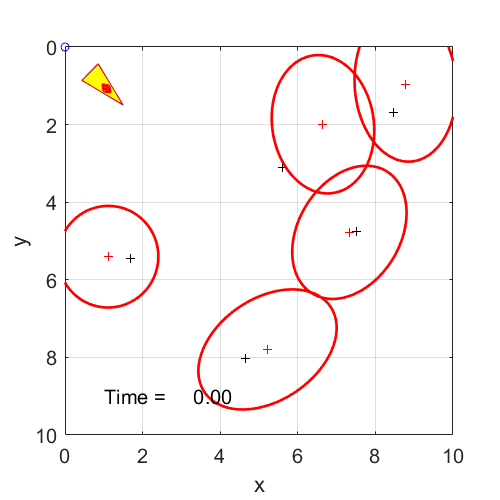

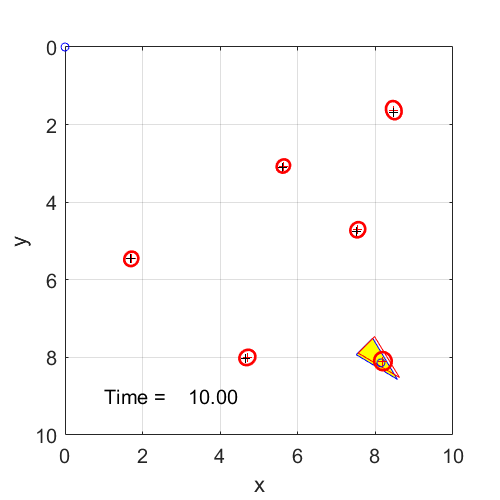

SLAM_skeleton()

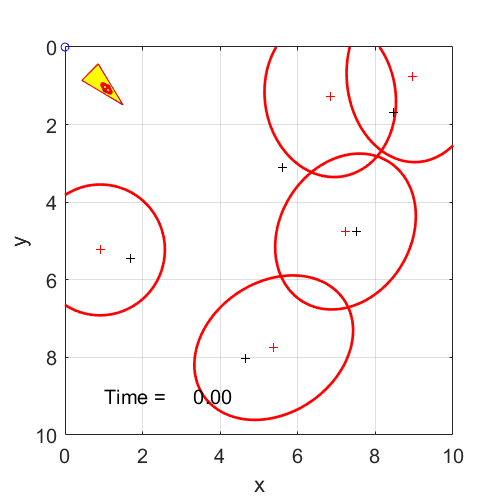

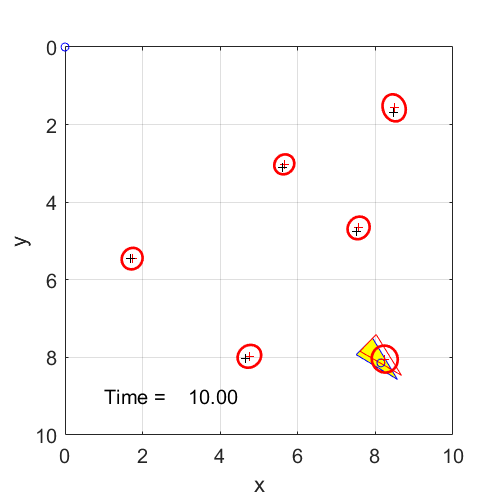

SLAM_skeleton(1.5)

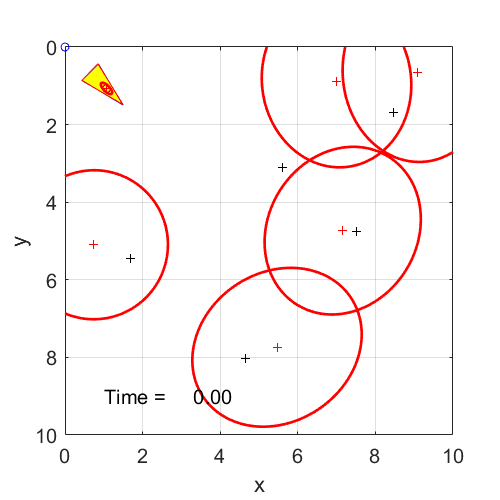

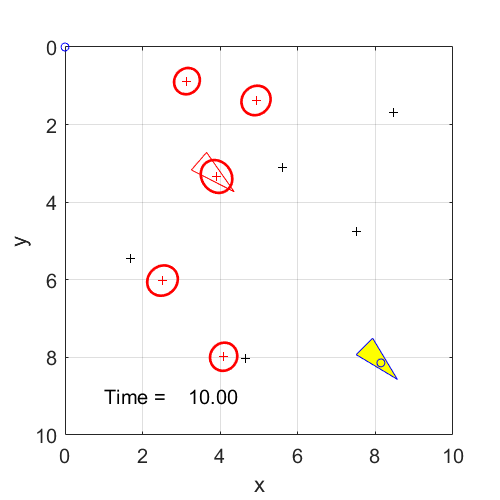

SLAM_skeleton(2)

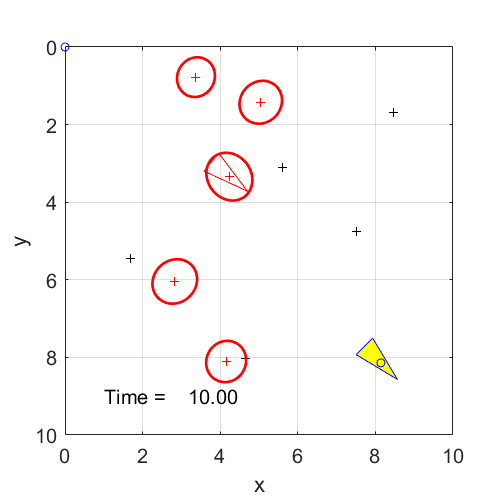

SLAM_skeleton(3)

## Problem 2

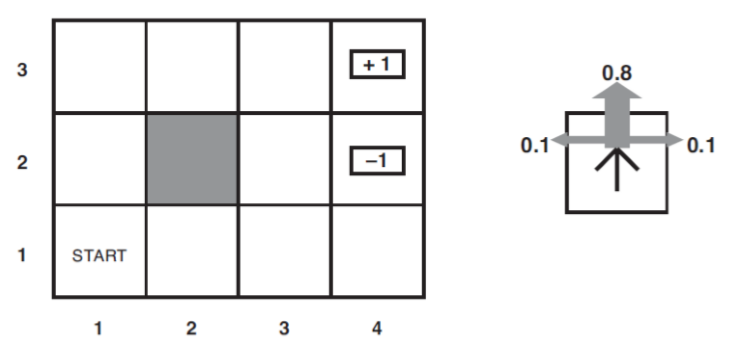

MDP_ValueIteration_skeleton